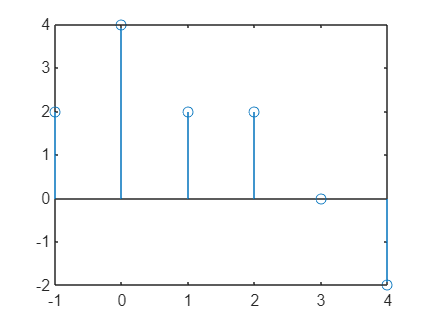

%Ex2

clear variables;
n = -7 : 7;
delta = @(n) n==0;
x = @(n) (delta(n) + 2*delta(n-1) - delta(n-3));
h = @(n) (2 * delta(n+1) + 2*delta(n-1));
%i
sx = 0; ex = 3; dtx = sx : ex;
sh = -1; eh = 1; dth = sh : eh;
dty1 = sx+sh : ex+eh;
y1 = conv(x(dtx),h(dth));
stem(dty1,y1)

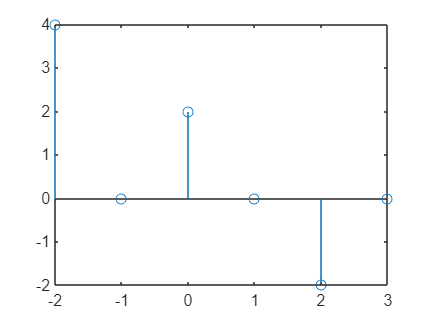

%ii
sx = -1; ex = 2; dtx2 = sx:ex;
sh = -1; eh = 1; dth2 = sh : eh;
dty2 = sx+sh : ex+eh;
y2 = conv(x(dtx+1),h(dth));
stem(dty2,y2)

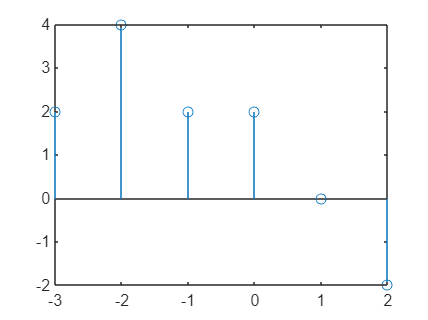

%iii
sx = 0; ex = 3; dtx = sx:ex;
sh = -3; eh = -1; dth = sh : eh;
dty3 = sx+sh : ex+eh;
y3 = conv(x(dtx),h(dth+2));
stem(dty3,y3)

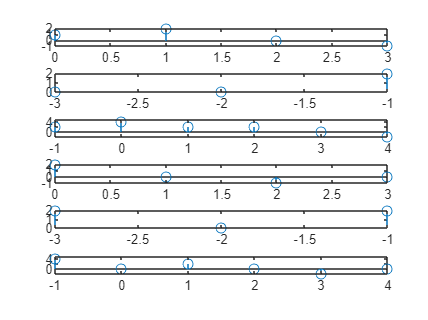


%b
figure,
subplot(6,1,1), stem(dtx,x(dtx));
subplot(6,1,2), stem(dth,h(dth));
subplot(6,1,3), stem(dty1,y1);
subplot(6,1,4), stem(dtx,x(dtx+1));
subplot(6,1,5), stem(dth,h(dth+2));
subplot(6,1,6), stem(dty1,y2);